# Planos y Curvas

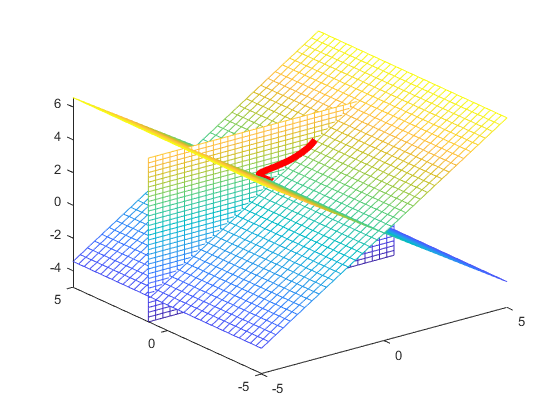

clc; clear
close all

syms t

% punto
x = 0;
y = 1;
z = pi/2;

plot3(x, y, z)

hold on

% curva
x1 = cos(t);
y1 = sin(t);
z1 = t;

fplot3(x1, y1, z1, "r", "LineWidth", 5)

syms u v

% plano normal
x2 = u;
y2  = v;
z2 = (pi / 2) + u;

fmesh(x2, y2, z2)

% plano osculador
x3 = u;
y3  = v;
z3 = (pi / 2) - u;

fmesh(x3, y3, z3)

% plano 3, no se usa
x4 = u;
y4  = 1;
z4 = v;

fmesh(x4, y4, z4)

hold off